## Tutorial 3.9

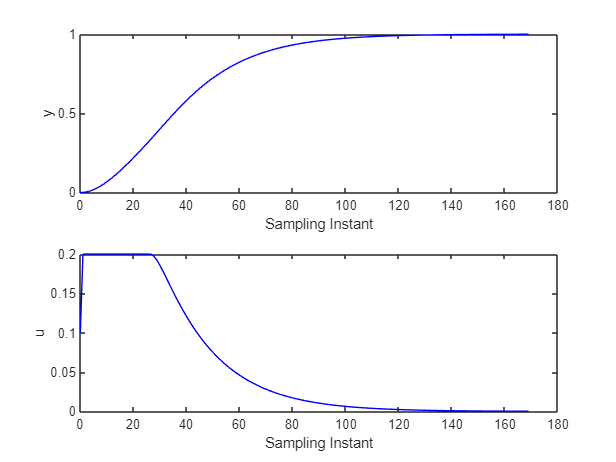

clear all; close all; clc;

% motor1.m
K=1; % gain of the motor
T=1; % time constant of the motor
h=0.1; % sampling interval
num=K;
den=conv([1 0],[T 1]);

[numd,dend]=c2dm(num,den,h);
Ap=zeros(3,3);
Ap(1,:)=[-dend(1,2:3) numd(1,3)];
Ap(2,:)=[1 0 0];
Ap(3,:)=[0 0 0];
Bp(1,1)=numd(1,2);
Bp(2,1)=0;
Bp(3,1)=1;
Cp(1,1)=1;
Cp(1,2)=0;
Cp(1,3)=0;
Dp(1,1)=0;

% Modelo aumentado
n1=3;
m1=1;
n_in=1;
A=eye(n1+m1,n1+m1);
A(1:n1,1:n1)=Ap;
A(n1+1:n1+m1,1:n1)=Cp*Ap;
B=zeros(n1+m1,n_in);
B(1:n1,:)=Bp;
B(n1+1:n1+m1,:)=Cp*Bp;
C=zeros(m1,n1+m1);
C(:,n1+1:n1+m1)=eye(m1,m1);

% Generar matrices requeridas para la función de costo 
% de control predictivo J

Q=C'*C;
R=0.3;
a=0.7;
N=1; %you can increase N
Np=46;
[Omega,Psi]=dmpc(A,B,a,N,Np,Q,R);

[A1,L0]=lagd(a,N);
K_mpc=L0'*(Omega\Psi);
Acl=A-B*K_mpc;
Pole_close=eig(Acl);

xm=zeros(n1,1);
N_sim=170;
u=0;
y=0;
y_delta_k=0;
y_delta_k_m1=0;
u_delta_k_m1=0;
r=[ones(1,200) ones(1,100) ones(1,200)];
Xf=[y_delta_k; y_delta_k_m1; u_delta_k_m1;
y-r(1,1)];
u_min=-0.3;
u_max=0.2;
deltau_min=-0.1;
deltau_max=0.1;
up=0.0;

for kk=1:N_sim
    eta=-(Omega\Psi)*Xf;
    deltau=L0'*eta;
    if (deltau>deltau_max) 
        deltau=deltau_max;
    end
    if (deltau<deltau_min)
        deltau=deltau_min;
    end
    u=up+deltau;
    
    if (u>u_max) 
        deltau=u_max-up;
        u=u_max;
    end
    
    if (u<u_min) 
        deltau=u_min-up;
        u=u_min; 
    end
    
    deltau1(1,kk)=deltau; %save data
    u1(1,kk)=u; %save data
    y1(1,kk)=y; %save data
    %%%%
    %plant simulation
    %%%%%%
    yp=y;
    xm_old=xm;
    xm=Ap*xm+Bp*u; % calculate xm(k+1)
    y=Cp*xm; %calculate y(k+1)
    %updating feedback state variable Xf
    
    y_delta_k_m1=y_delta_k;
    y_delta_k=y-yp;
    u_delta_k_m1=deltau;
    Xf=[y_delta_k;
    y_delta_k_m1;u_delta_k_m1;y-r(1,kk+1)];
    up=u;
end

k=0:(N_sim-1);

figure(1)
subplot(211)
plot(k,y1,'b')
ylabel('y')
xlabel('Sampling Instant')
subplot(212)
plot(k,u1,'b')
ylabel('u')
xlabel('Sampling Instant')

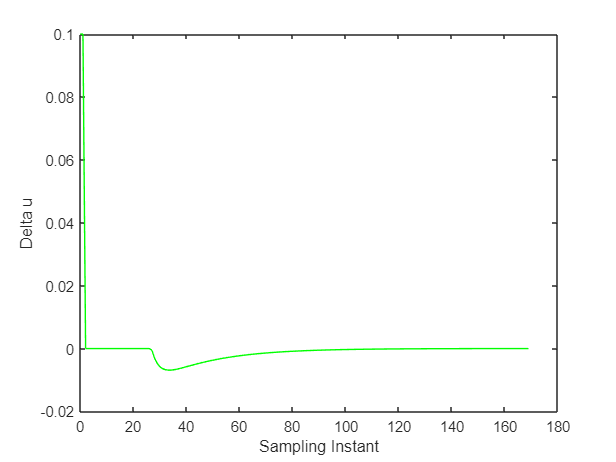


figure(2)
plot(k,deltau1,'g')
ylabel('Delta u')
xlabel('Sampling Instant')